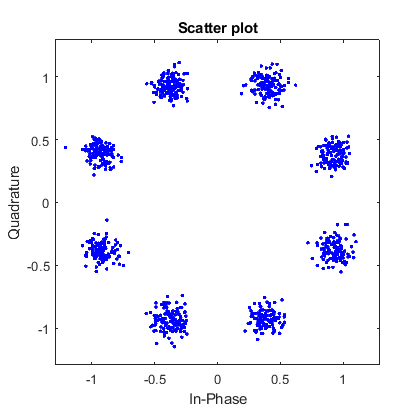

%esta es la prueba de github
j=18;
M = 8;
data = randi([0 M-1],1000,1);
txSig = pskmod(data,M,pi/M);
rxSig = awgn(txSig,20);
scatterplot(rxSig)

R = 2;
a = 0.4;
B = (R*(1+a))/(2)

B = 1.4000

%%% openExample('comm/ModulateAndDemodulate8PSKSignalExample')

t = -10:0.01:10;
R = 2

R = 2

a = 0.4

a = 0.4000

B = R*(1+a)/2

B = 1.4000

f = 0.5

f = 0.5000

fh = 0

fh = 0

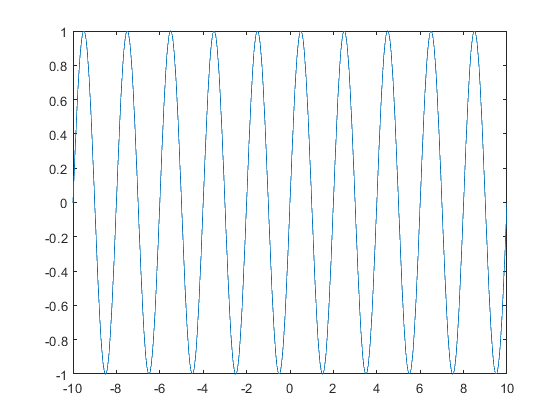

porta = sin(2*pi*f*t + fh);
figure,
plot(t, porta)


bits = randsrc(10,3,[0 1])

bits =      0     1     1
     0     1     0
     0     0     1
     1     0     1
     1     0     0
     1     1     1
     1     0     0
     1     0     1
     0     0     1
     0     1     1


simb = [0 0 0; 0 0 1; 0 1 0; 0 1 1; 1 0 0; 1 0 1; 1 1 0; 1 1 1]

simb =      0     0     0
     0     0     1
     0     1     0
     0     1     1
     1     0     0
     1     0     1
     1     1     0
     1     1     1



phase = [-112.5; -157.5; -67.5; -22.5; 112.5; 157.5; 67.5; 22.5]

phase =  -112.5000
 -157.5000
  -67.5000
  -22.5000
  112.5000
  157.5000
   67.5000
   22.5000



modul = 0

modul = 0

# TRABAJO

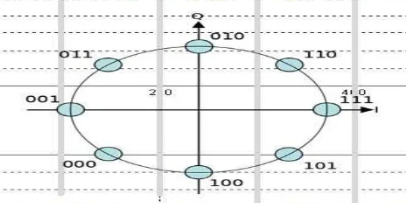

close all
clear all
clc

simb = [0 0 0; 0 0 1; 0 1 0; 0 1 1; 1 0 0; 1 0 1; 1 1 0; 1 1 1] %%% Simbolos de 8-PSK

simb =      0     0     0
     0     0     1
     0     1     0
     0     1     1
     1     0     0
     1     0     1
     1     1     0
     1     1     1


simb1 = [0 0 0 0 0 1 0 1 0 0 1 1 1 0 0 1 0 1 1 1 0 1 1 1] 

simb1 =      0     0     0     0     0     1     0     1     0     0     1     1     1     0     0     1     0     1     1     1     0     1     1     1


dSimb = [];  %%% Simbolos de 8-PSK en decimal
for i=1:length(simb)
    dSimb(i,1) = bi2de(simb(i,:),'left-msb');
    i=i+1;
end
dSimb

dSimb =      0
     1
     2
     3
     4
     5
     6
     7



phase = [225; 180; 90; 135; 270; 315; 45; 0]  %%% Fase en Grados

phase =    225
   180
    90
   135
   270
   315
    45
     0



S = []; %%% [Real, Imaginario]
for i=1:1:length(simb)
    S(i,1) = cos(phase(i)*pi/180);
    S(i,2) = sin(phase(i)*pi/180);   
end
S = round(S,3)

S =    -0.7070   -0.7070
   -1.0000         0
         0    1.0000
   -0.7070    0.7070
         0   -1.0000
    0.7070   -0.7070
    0.7070    0.7070
    1.0000         0


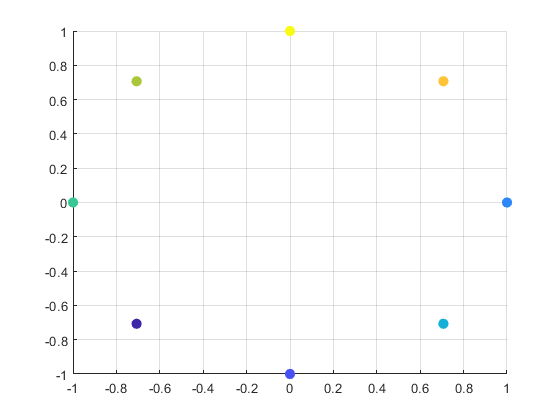


figure,
c = linspace(1,10,length(S(:,2)));
scatter(S(:,2),S(:,1),60,c,'filled')
grid on


n = 100000; %%% Numero de Simbolos
Data = randsrc(n,3,[0 1]) %%% Datos

Data =      0     1     1
     0     0     1
     0     0     0
     0     1     1
     0     0     1
     0     0     0
     1     1     0
     0     0     1
     1     1     1
     1     1     1



dData =  []; %%% Datos en decimal
for i=1:length(Data)
    dData(i,1) = bi2de(Data(i,:),'left-msb');
    i=i+1;
end
dData

dData =      3
     1
     0
     3
     1
     0
     6
     1
     7
     7


Out = [];  %%% Datos 8-PSK
for i=1:length(dData)
    for k=1:length(dSimb)
        if dData(i,1)== dSimb(k,1)
            Out(i,:) = S(k,:);
        end
        k=k+1;
    end
    i=i+1;
end
Out

Out =    -0.7070    0.7070
   -1.0000         0
   -0.7070   -0.7070
   -0.7070    0.7070
   -1.0000         0
   -0.7070   -0.7070
    0.7070    0.7070
   -1.0000         0
    1.0000         0
    1.0000         0


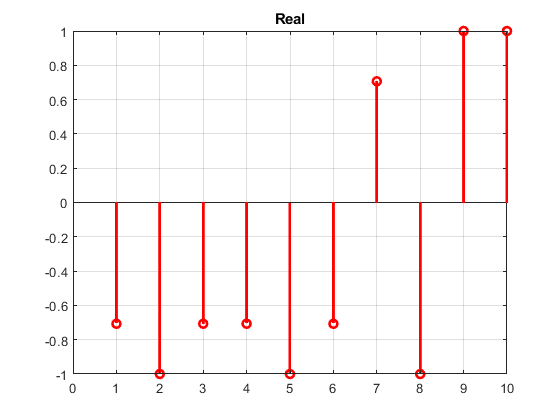


figure,
stem(Out(:,1),'r',"LineWidth",2)
title("Real")
axis([0 10 -inf inf])
grid on

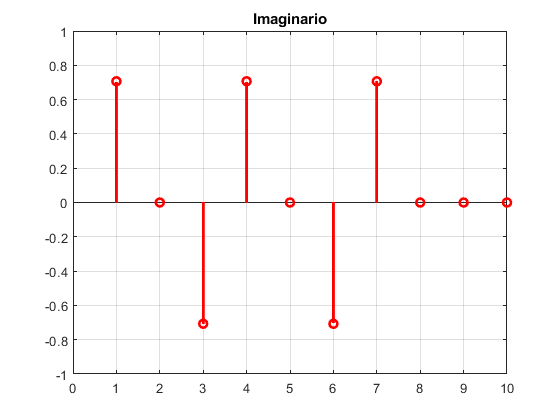


figure, 
stem(Out(:,2),'r',"LineWidth",2)
title("Imaginario")
axis([0 10 -inf inf])
grid on

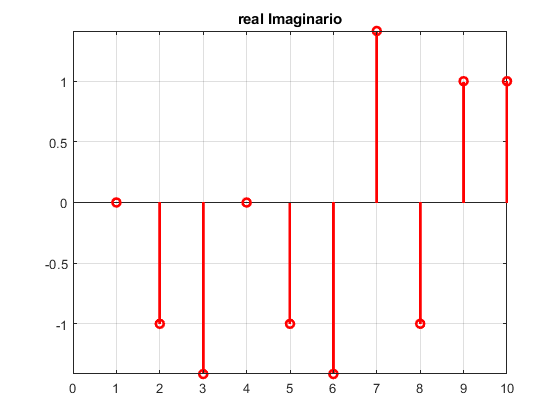



figure, 
stem(Out(:,1) + Out(:,2),'r',"LineWidth",2)
title("real Imaginario")
axis([0 10 -inf inf])
grid on